# Electric field of untapered optical fiber - HE11 mode

close all


## Input

% Taper diameter (m)
diam = 125e-6;

% Input power (W)
P = 10e-3;                     


## Parameters

n_eff = 1.4475;                 % Effective refractive index (Mode solver data 1.44622983) 
MFD = 10.4e-6;                  % Thorlabs SMF-28-J9 data

lambda = 1.55e-6;               % Wavelength (m)
k0 = 2 * pi / lambda;           % Free-space wavenumber
eps0 = 8.8542e-12;              % Free-space permittivity
n1 = 1.4508;                    % Core refractive index (Mode solver data 1.4492)
n2 = 1.4440;                    % Cladding refractive index (Mode solver data 1.444)
omega = 2 * pi * 3e8 / lambda;  % Angular frequency

b = diam / 2;                   % Cladding radius (m)
a = b / 15.24;                  % Core radius (m) 
beta = k0 * n_eff;              % Propagation constant

v = 1;                          % Mode order = 1 for HE11

% Core field amplitude
I = 4 * P / (pi * MFD^2);                   % (W/m^2) Laser intensity
E0 = sqrt(2 * I / (3e8 * n_eff * eps0));    % (V/m) Electric field amplitude

% Derived quantities
U = a * sqrt(k0^2 * n1^2 - beta^2);         % Core wavenumber 
W = a * sqrt(beta^2 - k0^2 * n2^2);         % Cladding decay constant 
V = 2*pi * a/lambda * sqrt(n1^2 - n2^2);    % Fiber parameter 

% Bessel coefficients
b1 = 1/(2*U*besselj(v,U)) * (besselj(v-1,U) - besselj(v+1,U));
b2 = -1/(2*W*besselk(v,W)) * (besselk(v-1,W) + besselk(v+1,W));
F2 = (V/(U*W))^2 * v/(b1 + b2);
a1 = (F2 - 1)/2;
a2 = (F2 + 1)/2;

% Initialize 2D amplitude map of field
grid_size = sqrt(2) * MFD * 5;            
resolution = 1000;              
x = linspace(-grid_size, grid_size, resolution);
y = linspace(-grid_size, grid_size, resolution);
[X, Y] = meshgrid(x, y);
R = sqrt(X.^2 + Y.^2);
Phi = atan2(Y, X);

% Initialize 2D field array
E_r_2D = zeros(size(R));
E_phi_2D = zeros(size(R));
E_z_2D = zeros(size(R));

## Fields

% Core field
core_idx = (R <= a);
E_r_2D(core_idx) = -1 / besselj(v, U) * ...
    (a1 * besselj(v-1, U * R(core_idx) / a) + ...
     a2 * besselj(v+1, U * R(core_idx) / a)) .* cos(v * Phi(core_idx));
E_phi_2D(core_idx) = -1 / besselj(v, U) * ...
    (a1 * besselj(v-1, U * R(core_idx) / a) - ...
     a2 * besselj(v+1, U * R(core_idx) / a)) .* -sin(v * Phi(core_idx));
E_z_2D(core_idx) = -1j * U/(a*beta) * besselj(v,U * R(core_idx) / a) / ...
    besselj(v,U) .* cos(v * Phi(core_idx));

% Cladding field 
clad_idx = (R > a);
E_r_2D(clad_idx) = -U / (W * besselk(v, W)) * ...
    (a1 * besselk(v-1, W * R(clad_idx) / a) - ...
     a2 * besselk(v+1, W * R(clad_idx) / a)) .* cos(v * Phi(clad_idx));
E_phi_2D(clad_idx) = -U / (W * besselk(v, W)) * ...
    (a1 * besselk(v-1, W * R(clad_idx) / a) + ...
     a2 * besselk(v+1, W * R(clad_idx) / a)) .* -sin(v * Phi(clad_idx));
E_z_2D(clad_idx) = -1j * U/(a*beta) * besselk(v,W * R(clad_idx) / a) / ...
    besselk(v,W) .* cos(v * Phi(clad_idx));

% Total field vector
E_vec = cat(3, E_r_2D, E_phi_2D, E_z_2D);
E_vec_cart = cat(3, ...
    E_r_2D .* cos(Phi) - E_phi_2D .* sin(Phi), ... 
    E_r_2D .* sin(Phi) + E_phi_2D .* cos(Phi), ...
    E_z_2D);


## Amplitude-Power matching

% Field magnitudes
E_mag = sqrt(sum(E_vec.^2, 3));
E_mag_cart = sqrt(sum(E_vec_cart.^2, 3));

% Normalize total E-field
E_vec = E_vec / max(E_mag(:));
E_vec_cart = E_vec_cart / max(E_mag_cart(:));

% % Scale total E-field with amplitude from input power
% E_vec = E_vec * E0;
% E_vec_cart = E_vec_cart * E0;

% Recompute (component) magnitudes
E_mag = sqrt(sum(E_vec.^2, 3));
E_mag_cart = sqrt(sum(E_vec_cart.^2, 3));

E_r = E_vec(:,:,1);
E_phi = E_vec(:,:,2);
E_z = imag(E_vec(:,:,3));

E_x = E_vec_cart(:,:,1);
E_y = E_vec_cart(:,:,2);
E_t = sqrt(E_vec(:,:,1).^2 + E_vec(:,:,2).^2);

disp(['Peak amplitude: ', num2str(max(E_mag(:))),' V/m']);

Peak amplitude: 1 V/m


## 2D Plot

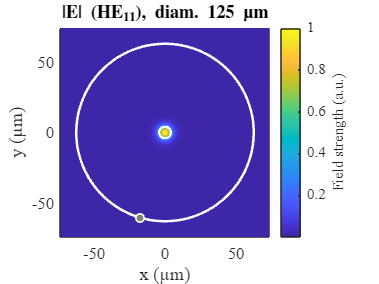

figure; hold on; box on;
imagesc(x * 1e6, y * 1e6, E_mag);  
viscircles([0, 0] * 1e6, a * 1e6, 'LineWidth', 0.5, 'Color', 'w'); % Show core 
viscircles([0, 0] * 1e6, b * 1e6, 'LineWidth', 0.5, 'Color', 'w'); % Show cladding
axis equal tight;
pbaspect([1 1 1]);
colormap default;
color=colorbar;
color.Label.String = 'Field strength (a.u.)';
title(['|E| (HE_{11}), diam. ',num2str(2*b*1e6),' µm']);
xlabel('x (µm)');
ylabel('y (µm)');

% Fonts to match LaTeX
set(gca, 'FontName', 'mlmodern', 'FontSize', 10);

hold off;


matlab2tikz('D:\Documents\Study\Graduation project\MATLAB\Export\Fiber_E_125um_norm.tex',...
    'relativeDataPath', 'Figures','showInfo', false,...
    'extraAxisOptions', {'width=\linewidth','axis equal image'});

% figure; hold on; box on;
% imagesc(x * 1e6, y * 1e6, E_t);  
% viscircles([0, 0] * 1e6, a * 1e6, 'LineWidth', 0.5, 'Color', 'w'); % Show core 
% viscircles([0, 0] * 1e6, b * 1e6, 'LineWidth', 0.5, 'Color', 'w'); % Show cladding
% axis equal;
% colormap default;
% color=colorbar;
% color.Label.String = 'Field strength (V/m)';
% title(['E_t (HE11), diam. ',num2str(2*b*1e6),' \mum']);
% xlabel('x (\mum)');
% ylabel('y (\mum)');
% hold off;

% figure; hold on; box on;
% imagesc(x * 1e6, y * 1e6, E_z);  
% viscircles([0, 0] * 1e6, a * 1e6, 'LineWidth', 0.5, 'Color', 'w'); % Show core 
% viscircles([0, 0] * 1e6, b * 1e6, 'LineWidth', 0.5, 'Color', 'w'); % Show cladding
% axis equal;
% colormap default;
% color=colorbar;
% color.Label.String = 'Field strength (V/m)';
% title(['E_z (HE11), diam. ',num2str(2*b*1e6),' \mum']);
% xlabel('x (\mum)');
% ylabel('y (\mum)');
% hold off;


## 1D Slices

% % Extract 1D slice from 2D grid (y = 0)
% y_idx = round(resolution / 2);  % Middle row corresponds to y = 0
% E_r_slice = E_r(y_idx, :);
% E_phi_slice = E_phi(:, y_idx);
% E_z_slice = E_z(y_idx, :);
% 
% E_t_slice = E_t(y_idx, :);
% E_mag_slice = E_mag(y_idx, :);
% E_mag_cart_slice = E_mag_cart(y_idx, :);
% 
% % Plot 
% figure; hold on
% plot(x * 1e6, E_r_slice, 'r', 'LineWidth', 2); 
% plot(x * 1e6, E_phi_slice, 'g', 'LineWidth', 2);
% plot(x * 1e6, E_z_slice, 'b', 'LineWidth', 2);
% xline([-b*1e6 -a*1e6 a*1e6 b*1e6],'--');
% title('1D Slices');
% xlabel('Radial distance (\mum)');
% ylabel('Field strength (V/m)');
% legend('E_r', 'E_\phi', 'E_z');
% grid on;
% 
% figure; hold on
% plot(x * 1e6, E_z_slice, 'r', 'LineWidth', 2); 
% xline([-b*1e6 -a*1e6 a*1e6 b*1e6],'--');
% title(['|E| (HE11), diam. ',num2str(2*b*1e6),' \mum']);
% xlabel('Radial distance (\mum)');
% ylabel('Field strength (V/m)');
% grid on;

drawnow;
